## Polarimetry Analysis - Additional Files: Custom colorbar

Last modified by Cristel Chandre (April 7, 2021)

Comments? [cristel.chandre@univ-amu.fr ](mailto:cristel.chandre@univ-amu.fr)

### Generate colorbar

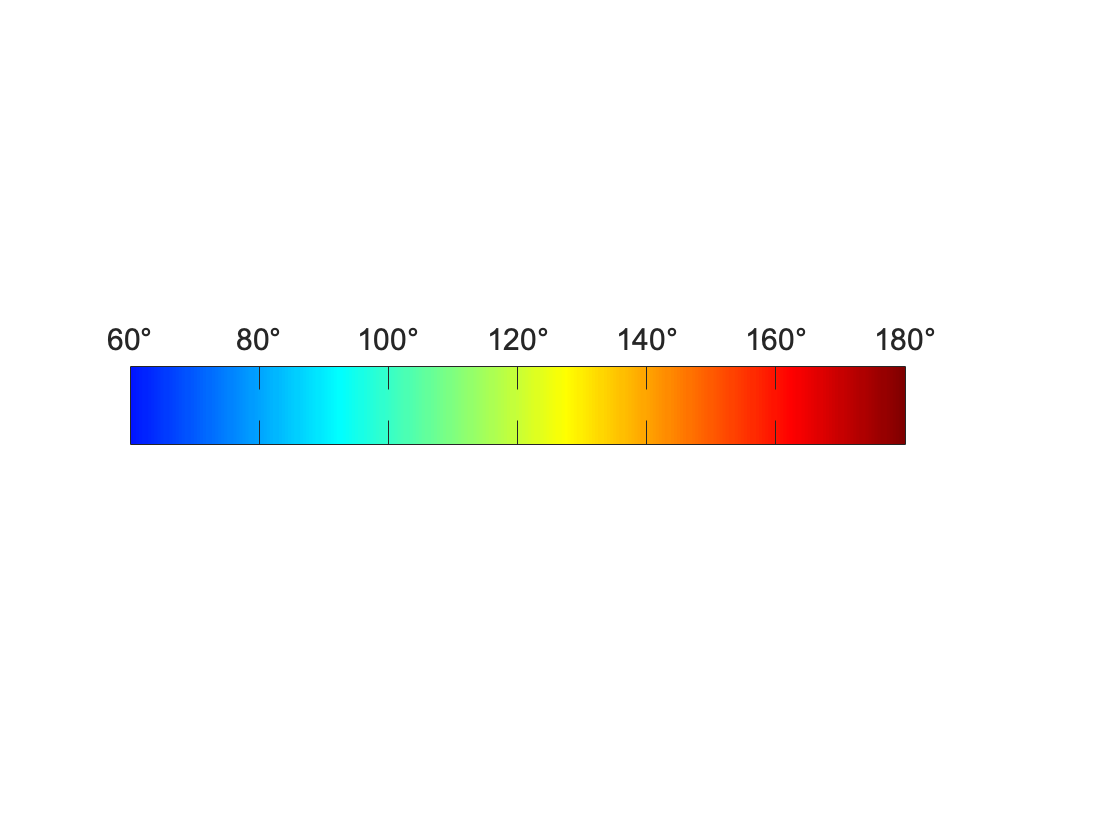

psimin = 60;
psimax = 180;
psidelta = 20;
cmap = "jet";
orientation = 2;
label_orientation = 3;
save_type = '.jpg';
resolution = 300;
aspect_ratio = 10;
font_size = 15;
font_type = 'Arial';

Nc = length(colormap(cmap));
psivec = linspace(psimin, psimax, Nc);
phi = ones(Nc, 1) * psivec;
if orientation == 1
    phi = phi.';
end
fig1 = figure(1);
pcolor(psivec, psivec, phi);
c = colorbar; 
c.Limits = [psimin psimax];
c.Visible = 'off';
caxis([40 180]);
shading flat
colormap(cmap);
set(gca, 'FontSize', font_size, 'FontName', font_type,'Layer', 'top', 'TickLength', [0.03 0.035]);

if orientation == 1
    set(gca, 'DataAspectRatio', [aspect_ratio, 1, 1]);
    yt = get(gca,'YTick');
    for k = 1:numel(yt)
        yt1{k} = sprintf('%d°', yt(k));
    end
    set(gca,'YTickLabel', yt1);
    set(gca, 'XTick', [], 'XTickLabels', [], 'YTick', psimin:psidelta:psimax);
    if label_orientation == 2
        set(gca, 'YAxisLocation', 'right');
    end
else
    set(gca, 'DataAspectRatio', [1, aspect_ratio, 1]);
    xt = get(gca,'XTick');
    for k = 1:numel(xt)
        xt1{k} = sprintf('%d°', xt(k));
    end
    set(gca,'XTickLabel', xt1);
    set(gca, 'YTick', [], 'YTickLabels', [], 'XTick', psimin:psidelta:psimax);
    if label_orientation == 3
        set(gca, 'XAxisLocation', 'top');
    end
end

### Save colorbar

exportgraphics(fig1, ['colorbar' save_type], 'Resolution', resolution);

disp(['colorbar' save_type '  saved...']);

colorbar.jpg  saved...


The data (.mat, .fig) used in this code are produced using the software Polarimetry Analysis [https://www.fresnel.fr/polarimetry/](https://www.fresnel.fr/polarimetry/)

Copyright (c) 2020 Cristel Chandre.

All rights reserved.

Redistribution and use in source and binary forms are permitted provided that the above copyright notice and this paragraph are duplicated in all such forms and that any documentation, advertising materials, and other materials related to such distribution and use acknowledge that the software was developed by the CNRS. The name of the CNRS may not be used to endorse or promote products derived from this software without specific prior written permission.

THIS SOFTWARE IS PROVIDED "AS IS" AND WITHOUT ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, WITHOUT LIMITATION, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE.